# Hypothesis testing

clc;
close all;
clear variables;

## Parameters

ma = [3; 1]; 
mb = [10; -4];

sigma_a = [1.7; 2];
sigma_b = [2; 1.4];

rho_a = -0.6;
rho_b = 0.7;

num_a = 500;
sum_b = 500;

## Samples

A = Samples(ma, sigma_a, rho_a,  num_a);
B = Samples(mb, sigma_b, rho_b, sum_b);

## Plotting


figure();
grid on; hold on; axis equal;
labels = {};

A.plot('b.'); labels{end+1} = 'A';
B.plot('r.'); labels{end+1} = 'B';

title('Odbirci');
xlabel('$x_1$', 'Interpreter',"latex")
ylabel('$x_2$', "Interpreter","latex")

syms x_1 x_2 real
X = [x_1; x_2];

line_width = 2;

### Bayes' test of least error


$$h(X) = -ln\left(\frac{f_1}{f_2}\right) = ln\left(\frac{P_1}{P_2}\right)$$


P = [0.5; 0.5];
h = -log(A.pdf_sym(X) / B.pdf_sym(X));
fimplicit(h == log(P(1) / P(2)), 'Color', 'g', 'LineWidth', line_width)
labels{end+1} = '$h(X) == 0$';


$$f(X) = const$$


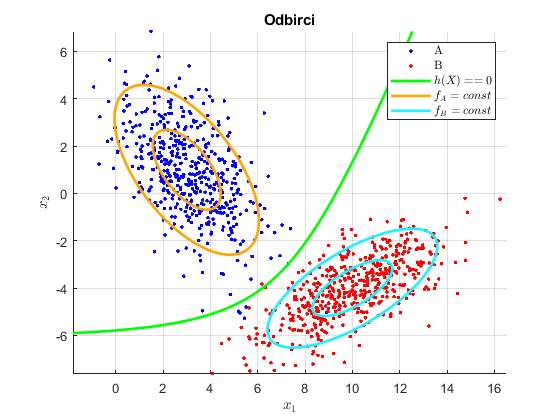

for const_pdf_val = [0.2 0.7]
    fimplicit(exp(-0.5 * (X - A.M)' * A.cov_mat ^ (-1) * (X - A.M)) == const_pdf_val, 'Color', '#FFA600', 'LineWidth', line_width)
    fimplicit(exp(-0.5 * (X - B.M)' * B.cov_mat ^ (-1) * (X - B.M)) == const_pdf_val, 'Color', '#1AF4FF', 'LineWidth', line_width)
end

labels{end+1} = '$f_A = const$';
labels{end+1} = '$f_B = const$';

leg = legend(labels);
set(leg,'Interpreter','latex');